# Problema 1

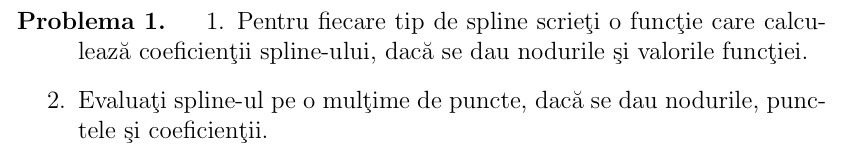

## 

## Spline natural

function coeffs = spline_natural(x, y)
% INPUT:
%   x - vectorul nodurilor (valori strict crescatoare) [x0, x1, ..., xn]
%   y - vectorul valorilor functiei f(x) in aceste noduri [y0, y1, ..., yn]
%
% OUTPUT:
%   coeffs - structura care contine coeficientii pentru fiecare polinom cubic
%            pe intervalul [x(i), x(i+1)]:
%       coeffs.a - coeficientul liber (corespunde y(i))
%       coeffs.b - coeficientul lui (x - x_i)
%       coeffs.c - coeficientul lui (x - x_i)^2
%       coeffs.d - coeficientul lui (x - x_i)^3
%       coeffs.x - capetele stangi ale intervalelor (x(1:end-1))

    n = length(x);            % numarul de noduri
    h = diff(x);              % pasii h(i) = x(i+1) - x(i)

    alpha = zeros(n-1,1);     % partea dreaptă a sistemului tridiagonal

    % Construim vectorul alpha pentru interior (i = 2,..,n-1)
    for i = 2:n-1
        alpha(i) = (3/h(i))*(y(i+1) - y(i)) - (3/h(i-1))*(y(i) - y(i-1));
    end

    % Initializam vectorii pentru metoda Thomas (rezolvarea sistemului tridiagonal)
    l = ones(n,1);    % diagonala principala (initializata cu 1)
    mu = zeros(n,1);  % coeficientii de pe supradiagonala
    z = zeros(n,1);   % solutia temporara pentru sistemul tridiagonal

    % Construim sistemul tridiagonal pentru determinarea coeficientilor c
    for i = 2:n-1
        l(i) = 2*(x(i+1) - x(i-1)) - h(i-1)*mu(i-1);  % diagonala principala actualizata
        mu(i) = h(i)/l(i);                           % supradiagonala
        z(i) = (alpha(i) - h(i-1)*z(i-1))/l(i);       % partea dreapta
    end

    % Vectorii coeficientilor spline-ului
    a = y;                     % coeficientul liber este y(i)
    b = zeros(n-1,1);          % coeficientul lui (x - x_i)
    c = zeros(n,1);            % coeficientul lui (x - x_i)^2
    d = zeros(n-1,1);          % coeficientul lui (x - x_i)^3

    % Back-substitution pentru determinarea lui c (derivata a doua)
    for j = n-1:-1:1
        c(j) = z(j) - mu(j)*c(j+1);   % c(i) calculat din dreapta spre stanga
        b(j) = (a(j+1) - a(j))/h(j) - h(j)*(2*c(j) + c(j+1))/3;  % coef. liniar
        d(j) = (c(j+1) - c(j)) / (3*h(j));                       % coef. cubic
    end

    % Grupam coeficientii in structura de iesire
    coeffs = struct('a', a(1:end-1), ...  % toate a(i) pentru i=1,..,n-1
                    'b', b, ...
                    'c', c(1:end-1), ...
                    'd', d, ...
                    'x', x(1:end-1));    % capetele intervalelor

end

function values = eval_spline_N(x_eval, coeffs)
% INPUT:
%   x_eval - vectorul cu puncte unde dorim sa evaluam spline-ul
%   coeffs - structura cu coeficientii spline-ului, obtinuta din spline_natural():
%       .a - coeficientul liber
%       .b - coeficientul lui (x - x_i)
%       .c - coeficientul lui (x - x_i)^2
%       .d - coeficientul lui (x - x_i)^3
%       .x - vectorul cu capetele stangi ale intervalelor [x_0, x_1, ..., x_{n-1}]
%
% OUTPUT:
%   values - vector cu valorile spline-ului evaluate in fiecare punct din x_eval

    n = length(coeffs.x);               % numarul de intervale (n = nr. noduri - 1)
    values = zeros(size(x_eval));      % initializam vectorul rezultat

    % Parcurgem fiecare punct unde vrem sa evaluam spline-ul
    for i = 1:length(x_eval)
        % Cautam in ce interval [x_j, x_{j+1}] se afla x_eval(i)
        for j = 1:n
            % Verificam daca punctul se afla in intervalul curent
            if x_eval(i) >= coeffs.x(j) && (j == n || x_eval(i) < coeffs.x(j+1))
                dx = x_eval(i) - coeffs.x(j);  % distanta fata de capatul stang al intervalului

                % Aplicam formula polinomului spline pe intervalul [x_j, x_{j+1}]:
                % S(x) = a_j + b_j*(x - x_j) + c_j*(x - x_j)^2 + d_j*(x - x_j)^3
                values(i) = coeffs.a(j) + ...
                            coeffs.b(j)*dx + ...
                            coeffs.c(j)*dx^2 + ...
                            coeffs.d(j)*dx^3;

                break;  % am gasit intervalul potrivit, iesim din bucla interioara
            end
        end
    end
end


function [spline_vals, spline_pieces, max_err] = aplicaSplineNatural(f, x_noduri, x_eval)
% APLICASPLINENATURAL - Calculeaza spline-ul natural si il evalueaza
%
% INPUT:
%   f         - functia f(x) data ca functie anonima
%   x_noduri  - vector cu nodurile de interpolare (crescator)
%   x_eval    - vector cu punctele in care se evalueaza spline-ul
%
% OUTPUT:
%   spline_vals    - valorile spline-ului natural in punctele x_eval
%   spline_pieces  - celula cu expresiile simbolice ale polinoamelor pe fiecare interval
%   max_err        - eroarea maxima fata de functia originala

    syms x

    % 1. Calculeaza valorile in noduri
    y = f(x_noduri);

    % 2. Calculeaza coeficientii spline-ului natural
    coeffs = spline_natural(x_noduri, y);

    % 3. Evalueaza spline-ul in punctele dorite
    spline_vals = eval_spline_N(x_eval, coeffs);

    % 4. Verifica derivata a doua in capete
    Spp_start = 6 * coeffs.d(1);           % S''(x1)
    Spp_end   = 6 * coeffs.d(end);         % S''(xn)
    if abs(Spp_start) > 1e-2 || abs(Spp_end) > 1e-2
        warning('Atentie: derivata a doua in capete NU este ≈ 0 (%.2f, %.2f)', Spp_start, Spp_end);
    end

    % 5. Genereaza expresiile simbolice pe fiecare interval
    spline_pieces = cell(1, length(coeffs.a));
    for i = 1:length(coeffs.a)
        dx = x - coeffs.x(i);
        S = coeffs.a(i) + coeffs.b(i)*dx + coeffs.c(i)*dx^2 + coeffs.d(i)*dx^3;
        spline_pieces{i} = simplify(S);
    end

    % 6. Calculeaza eroarea maxima
    f_eval = f(x_eval);
    max_err = max(abs(f_eval - spline_vals));
end


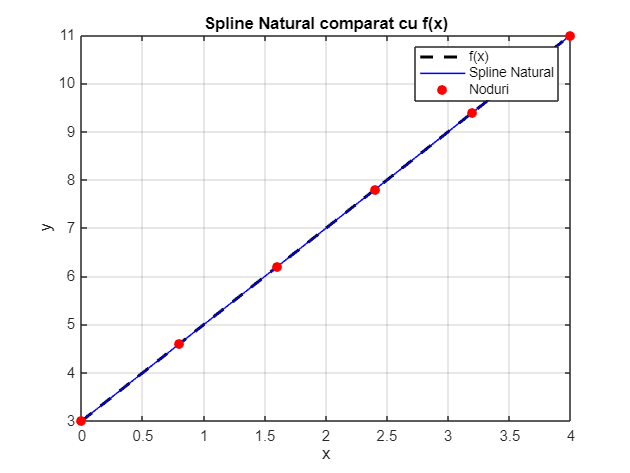

f = @(x) 2*x + 3;              % functia f(x)
a = 0; b = 4;                  % capetele intervalului
n_noduri = 6;                  % cate noduri vrem
n_eval = 400;                  % cate puncte vrem sa evaluam spline-ul

x_noduri = linspace(a, b, n_noduri);     % noduri pentru interpolare
x_eval = linspace(a, b, n_eval);         % puncte de evaluare

[yy_spline, spline_sym, eroare] = aplicaSplineNatural(f, x_noduri, x_eval);

figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy_spline, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Natural', 'Noduri');
title('Spline Natural comparat cu f(x)');
xlabel('x'); ylabel('y');
grid on;


% disp('Polinoamele spline-ului pe intervale:');
% for i = 1:length(spline_sym)
%     fprintf('Interval [%f, %f]:\n', x_noduri(i), x_noduri(i+1));
%     disp(spline_sym{i});
% end

fprintf('Eroare maxima de aproximare: %.2e\n', eroare);

Eroare maxima de aproximare: 1.78e-15


## Spline complet

function coef = spline_complet(x, y, fp0, fpn)
% INPUT:
%   x    - noduri (vector strict crescator)
%   y    - valori f(x) in noduri
%   fp0  - derivata f'(x_0)
%   fpn  - derivata f'(x_n)
%
% OUTPUT:
%   coef - matrice (n-1)x4 cu coeficientii [a, b, c, d] pentru fiecare interval

    n = length(x);
    h = diff(x);  % lungimile intervalelor

    % Construim sistemul tridiagonal pentru c
    A = zeros(n);      
    rhs = zeros(n,1);  

    % Capatul stang: derivata cunoscuta f'(x0) = fp0
    A(1,1) = 2*h(1); 
    A(1,2) = h(1);
    rhs(1) = 3*((y(2)-y(1))/h(1) - fp0);

    % Capatul drept: derivata cunoscuta f'(xn) = fpn
    A(n,n-1) = h(end);
    A(n,n) = 2*h(end);
    rhs(n) = 3*(fpn - (y(end)-y(end-1))/h(end));

    % Ecuatii interioare
    for i = 2:n-1
        A(i,i-1) = h(i-1);
        A(i,i)   = 2*(h(i-1) + h(i));
        A(i,i+1) = h(i);
        rhs(i) = 3*((y(i+1)-y(i))/h(i) - (y(i)-y(i-1))/h(i-1));
    end

    % Rezolvam sistemul: obtinem c_i = S''(x_i)/2
    c = A \ rhs;

    % Calculam coeficientii spline-ului pe fiecare interval
    a = y(1:end-1);
    b = zeros(n-1,1);
    d = zeros(n-1,1);

    for i = 1:n-1
        b(i) = (y(i+1)-y(i))/h(i) - h(i)*(2*c(i)+c(i+1))/3;
        d(i) = (c(i+1)-c(i))/(3*h(i));
    end

    % Returnam coeficientii: coloane [a b c d]
    coef = [a(:), b(:), c(1:end-1), d(:)];
end

function values = eval_spline_C(x, coef, x_eval)
% INPUT:
%   x       - nodurile [x0, x1, ..., xn]
%   coef    - coeficientii pe intervale (a, b, c, d)
%   x_eval  - punctele unde evaluam spline-ul
%
% OUTPUT:
%   values  - valori spline evaluate in punctele x_eval

    n = length(x);
    values = zeros(size(x_eval));

    for j = 1:length(x_eval)
        % Gasim in ce interval se afla x_eval(j)
        i = find(x_eval(j) >= x(1:end-1) & x_eval(j) <= x(2:end), 1, 'first');

        % Daca e in afara domeniului, alegem cel mai apropiat interval
        if isempty(i)
            i = (x_eval(j) < x(1)) * 1 + (x_eval(j) > x(end)) * (n - 1);
        end

        dx = x_eval(j) - x(i);
        a = coef(i,1); b = coef(i,2);
        c = coef(i,3); d = coef(i,4);

        values(j) = a + b*dx + c*dx^2 + d*dx^3;
    end
end

function este_derivabila = esteDerivabilaLaCapete(f, x, tol)
    % Verifica daca derivata la capete poate fi aproximata stabil
    h = 1e-5;
    d_st0 = (f(x(1)) - f(x(1) - h)) / h;
    d_dr0 = (f(x(1) + h) - f(x(1))) / h;

    d_stn = (f(x(end)) - f(x(end) - h)) / h;
    d_drn = (f(x(end) + h) - f(x(end))) / h;

    este_derivabila = abs(d_st0 - d_dr0) < tol && abs(d_stn - d_drn) < tol;
end

function [spline_vals, spline_pieces, err_max] = aplicaSplineComplet(f, x_noduri, x_eval)
% APLICASPLINECOMPLET - Aplica spline complet cu derivata aproximata numeric
%
% INPUT:
%   f         - functie anonima (f(x))
%   x_noduri  - noduri de interpolare (crescator)
%   x_eval    - puncte pentru evaluare
%
% OUTPUT:
%   spline_vals   - valori spline evaluate in x_eval
%   spline_pieces - celula cu expresii simbolice pe fiecare interval
%   err_max       - eroare maxima fata de f(x)

    if ~esteDerivabilaLaCapete(f, x_noduri, 1e-3)
        warning(['Functia nu este derivabila numeric la capete.\n' ...
                 'Spline complet NU este recomandat. Foloseste spline natural.']);
    end

    % Derivata aproximata la capete (formula centrata)
    h = 1e-5;
    fp0 = (f(x_noduri(1) + h) - f(x_noduri(1) - h)) / (2*h);
    fpn = (f(x_noduri(end) + h) - f(x_noduri(end) - h)) / (2*h);

    y = f(x_noduri);
    coef = spline_complet(x_noduri, y, fp0, fpn);
    spline_vals = eval_spline_C(x_noduri, coef, x_eval);

    % Polinoame simbolice
    syms x
    spline_pieces = cell(1, length(x_noduri)-1);
    for i = 1:length(spline_pieces)
        dx = x - x_noduri(i);
        S = coef(i,1) + coef(i,2)*dx + coef(i,3)*dx^2 + coef(i,4)*dx^3;
        spline_pieces{i} = simplify(S);
    end

    % Eroare
    err_max = max(abs(f(x_eval) - spline_vals));
end

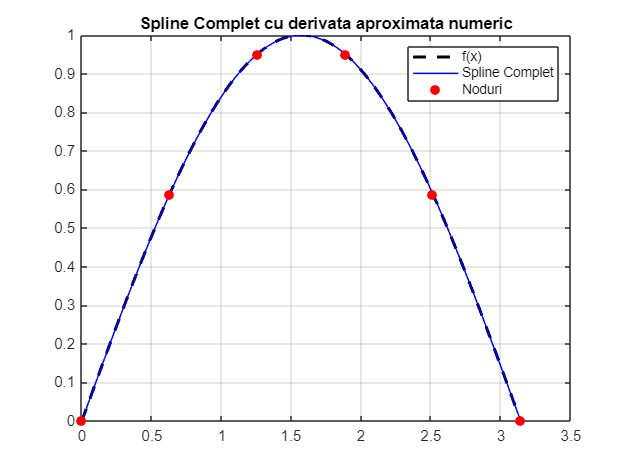

f = @(x) sin(x);                   % functia 
a = 0; b = pi;                     % interval
n = 6;                             % numar de noduri
x_noduri = linspace(a, b, n);     
x_eval = linspace(a, b, 400);

[yy, polinoame, eroare] = aplicaSplineComplet(f, x_noduri, x_eval);  % nu mai dam df

% Grafic
figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Complet', 'Noduri');
title('Spline Complet cu derivata aproximata numeric');
grid on;


% Afisare formule spline
% disp('Polinoamele spline-ului pe intervale:');
% for i = 1:length(polinoame)
%     fprintf('Interval [%f, %f]:\n', x_noduri(i), x_noduri(i+1));
%     disp(polinoame{i});
% end

fprintf('Eroare maxima de aproximare: %.2e\n', eroare);

Eroare maxima de aproximare: 4.34e-04


## Spline cu derivate de ordinul al doilea

function coef = spline_deriv2(x, y, m1, mn)
% INPUT:
%   x  - vectorul nodurilor (ordonate strict crescator)
%   y  - valorile functiei f(x) in noduri
%   m1 - derivata a doua in capatul stang (f''(x_0))
%   mn - derivata a doua in capatul drept (f''(x_n))
%
% OUTPUT:
%   coef - matrice cu coeficientii [a, b, c, d] pentru fiecare polinom cubic

    n = length(x);         % numar de noduri
    h = diff(x);           % lungimile subintervalelor

    % Initializam sistemul liniar A * c = rhs
    A = zeros(n);          % matrice tridiagonala (n x n)
    rhs = zeros(n,1);      % termenii liberi

    % Impunem derivata a doua la capete
    A(1,1) = 1; rhs(1) = m1;
    A(n,n) = 1; rhs(n) = mn;

    % Completam ecuatiile din interior (relatia standard pentru spline cubic)
    for i = 2:n-1
        A(i,i-1) = h(i-1);
        A(i,i)   = 2*(h(i-1) + h(i));
        A(i,i+1) = h(i);
        rhs(i) = 3*((y(i+1)-y(i))/h(i) - (y(i)-y(i-1))/h(i-1));
    end

    % Rezolvam sistemul tridiagonal => obtinem vectorul c (f''/2)
    c = A \ rhs;

    % Calculam coeficientii b si d pentru fiecare interval
    a = y(1:end-1);
    b = zeros(n-1,1);
    d = zeros(n-1,1);
    for i = 1:n-1
        b(i) = (y(i+1)-y(i))/h(i) - h(i)*(2*c(i)+c(i+1))/3;
        d(i) = (c(i+1)-c(i))/(3*h(i));
    end

    % Grupam coeficientii pe coloane: [a b c d]
    coef = [a(:), b, c(1:end-1), d];
end

function ok = esteDerivataA2LaCapete(f, x, tol)
% INPUT:
%   f   - functie anonima f(x)
%   x   - vectorul de noduri (folosim x(1) si x(end))
%   tol - toleranta relativa (default: 1e-2)
%
% OUTPUT:
%   ok  - true daca f'' este stabil numeric in capete

    if nargin < 3
        tol = 1e-1;
    end

    h = 1e-5;

    % Aproximam f''(x) la capete folosind formula centrata
    fpp_start = (f(x(1)+h) - 2*f(x(1)) + f(x(1)-h)) / h^2;
    fpp_end   = (f(x(end)+h) - 2*f(x(end)) + f(x(end)-h)) / h^2;

    % Verificam ca valorile sa fie finite
    if ~isfinite(fpp_start) || ~isfinite(fpp_end)
        ok = false;
        return;
    end

    %Calculam eroare relativa intre derivarile din capete
    medie = 0.5 * (abs(fpp_start) + abs(fpp_end));
    if medie < 1e-8
        diff_rel = abs(fpp_start - fpp_end);  % evitare instabilitate
    else
        diff_rel = abs(fpp_start - fpp_end) / medie;  % eroare relativa
    end

    % Returnam true doar daca diferenta este sub toleranta
    if diff_rel < tol
        ok = true;
    else
        ok = false;
    end
end


function [spline_vals, spline_pieces, err_max] = aplicaSplineDeriv2(f, x_noduri, x_eval)
% APLICASPLINEDERIV2 - Calculeaza si evalueaza spline-ul cu derivata a doua impusa
%
% INPUT:
%   f         - functie de interpolat (anonima)
%   x_noduri  - noduri unde construim spline-ul
%   x_eval    - puncte in care evaluam spline-ul
%
% OUTPUT:
%   spline_vals   - valorile spline-ului in punctele x_eval
%   spline_pieces - celula cu expresii simbolice ale polinoamelor
%   err_max       - eroarea maxima fata de functia f(x)

    % 1. Verificam daca derivata a doua este stabila numeric la capete
    if ~esteDerivataA2LaCapete(f, x_noduri)
        warning('Derivata a doua in capete nu pare stabila numeric.');
    end

    % 2. Aproximam derivata a doua in capete
    h_ = 1e-6;
    m1 = (f(x_noduri(1)+h_) - 2*f(x_noduri(1)) + f(x_noduri(1)-h_)) / h_^2;
    mn = (f(x_noduri(end)+h_) - 2*f(x_noduri(end)) + f(x_noduri(end)-h_)) / h_^2;

    % 3. Evaluam functia in noduri
    y = f(x_noduri);

    % 4. Construim spline-ul
    coef = spline_deriv2(x_noduri, y, m1, mn);

    % 5. Evaluam spline-ul in punctele dorite
    spline_vals = eval_spline_C(x_noduri, coef, x_eval);

    % 6. Generam polinoamele simbolice pe fiecare interval
    syms x
    spline_pieces = cell(1, length(x_noduri)-1);
    for i = 1:length(spline_pieces)
        dx = x - x_noduri(i);
        S = coef(i,1) + coef(i,2)*dx + coef(i,3)*dx^2 + coef(i,4)*dx^3;
        spline_pieces{i} = simplify(S);
    end

    % 7. Calculam eroarea maxima de aproximare
    err_max = max(abs(f(x_eval) - spline_vals));
end

f = @(x) x.^3 + 2*x.^2 - x + 5;   % functie perfect derivabila
a = 1;
b = 2;
n = 6;

x_noduri = linspace(a, b, n);
x_eval = linspace(a, b, 400);

[yy, polinoame, eroare] = aplicaSplineDeriv2(f, x_noduri, x_eval);

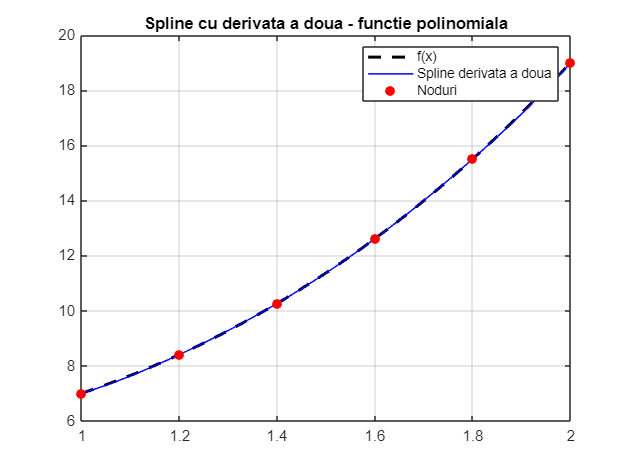


% Afisare grafica
figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline derivata a doua', 'Noduri');
title('Spline cu derivata a doua - functie polinomiala');
grid on;


% Afisare eroare
fprintf('Eroare maxima: %.2e\n', eroare);

Eroare maxima: 3.15e-02


## Spline Periodic

function coef = spline_periodic(x, y)
% SPLINE_PERIODIC - Calculeaza coeficientii spline-ului cubic periodic
%
% INPUT:
%   x - vectorul nodurilor (strict crescator): [x0, x1, ..., xn]
%   y - valorile functiei f(x) in noduri:      [y0, y1, ..., yn]
%
% OUTPUT:
%   coef - matrice (n-1) x 4 cu coeficientii spline-ului pe fiecare interval [xi, xi+1]:
%          fiecare linie: [a_i, b_i, c_i, d_i] corespunzand:
%          S_i(x) = a + b*(x - x_i) + c*(x - x_i)^2 + d*(x - x_i)^3

    n = length(x);           % numarul de noduri
    h = diff(x);             % lungimea fiecarui interval [x(i+1) - x(i)]

    % Initializam matricea A (tridiagonala cu elemente ciclice) si vectorul termenilor liberi
    A = zeros(n);           
    rhs = zeros(n, 1);      

    % ----------- CONSTRUCTIA SISTEMULUI LINEAR ------------

    % 1. Prima ecuatie (conditia de periodicitate in capatul stang)
    A(1,1)   = 2*(h(1)+h(end));   % diagonala principala
    A(1,2)   = h(1);              % urmatorul element
    A(1,end) = h(end);            % legatura ciclica cu ultimul nod
    rhs(1)   = 3*((y(2)-y(1))/h(1) - (y(end)-y(end-1))/h(end));  % derivata egala la capete

    % 2. Ecuatiile obisnuite pentru nodurile interioare (i = 2,...,n-1)
    for i = 2:n-1
        A(i,i-1) = h(i-1);                            % subdiagonala
        A(i,i)   = 2*(h(i-1) + h(i));                 % diagonala principala
        A(i,i+1) = h(i);                              % supradiagonala
        rhs(i)   = 3*((y(i+1)-y(i))/h(i) - (y(i)-y(i-1))/h(i-1));  % termenul liber
    end

    % 3. Ultima ecuatie: impune c(1) = c(n) => periodicitate a derivatelor a doua
    A(end,1)   = 1;
    A(end,end) = -1;
    rhs(end)   = 0;

    % -------------- REZOLVARE SISTEM --------------

    % Rezolva sistemul liniar A * c = rhs
    c = A \ rhs;

    % -------------- CALCUL COEFICIENTI SPLINE --------------

    a = y(1:end-1);       % coeficientul constant (fiecare S_i incepe din y(i))
    b = zeros(n-1,1);     % coeficientul lui (x - x_i)
    d = zeros(n-1,1);     % coeficientul lui (x - x_i)^3

    % Parcurgem fiecare interval [x(i), x(i+1)] pentru a calcula coeficientii
    for i = 1:n-1
        % coef. b = panta ajustata cu derivata a doua
        b(i) = (y(i+1)-y(i))/h(i) - h(i)*(2*c(i)+c(i+1))/3;

        % coef. d = diferenta derivatelor a doua, scalata
        d(i) = (c(i+1)-c(i))/(3*h(i));
    end

    % Rezultatul: coef = [a_i, b_i, c_i, d_i] pentru fiecare polinom
    coef = [a(:), b, c(1:end-1), d(:)];
end


function este = estePeriodica(f, a, b, tol)
% INPUT:
%   f   - functie anonima f(x)
%   a,b - capetele intervalului [a, b]
%   tol - toleranta numerica (optional, default = 1e-4)
%
% OUTPUT:
%   este - boolean: true daca f si f' sunt egale in capete (cu eroare < tol)

    if nargin < 4
        tol = 1e-4;
    end

    h = 1e-5;  % pas mic pentru derivare numerica

    % Derivata prima la capete (formula centrata)
    fpa = (f(a + h) - f(a - h)) / (2*h);
    fpb = (f(b + h) - f(b - h)) / (2*h);

    % Verificam daca valorile si derivarile sunt apropiate
    este = abs(f(a) - f(b)) < tol && abs(fpa - fpb) < tol;
end


function [spline_vals, spline_pieces, err_max] = aplicaSplinePeriodic(f, x_noduri, x_eval)
% INPUT:
%   f         - functie anonima f(x)
%   x_noduri  - vector de noduri (x0 < x1 < ... < xn)
%   x_eval    - puncte unde vrem sa evaluam spline-ul
%
% OUTPUT:
%   spline_vals    - valorile spline-ului in x_eval
%   spline_pieces  - celula cu polinoamele simbolice pe intervale
%   err_max        - eroarea maxima de interpolare f - spline

    % Verificare periodicității funcției la capete
    if ~estePeriodica(f, x_noduri(1), x_noduri(end))
        warning('Functia NU este aproximativ periodica in capetele intervalului!');
    end

    % Construim vectorul y
    y = f(x_noduri);

    % Apelam functia spline_periodic pentru coeficienti
    coef = spline_periodic(x_noduri, y);

    % Evaluam spline-ul in punctele dorite
    spline_vals = eval_spline_C(x_noduri, coef, x_eval);

    % Generam formule simbolice ale spline-ului pe fiecare interval
    syms x
    spline_pieces = cell(1, length(x_noduri)-1);
    for i = 1:length(spline_pieces)
        dx = x - x_noduri(i);
        S = coef(i,1) + coef(i,2)*dx + coef(i,3)*dx^2 + coef(i,4)*dx^3;
        spline_pieces{i} = simplify(S);
    end

    % Calculam eroarea maxima comparativ cu f
    err_max = max(abs(f(x_eval) - spline_vals));
end

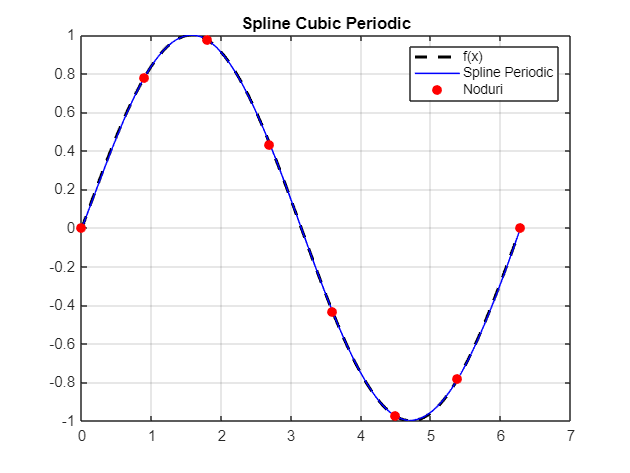

f = @(x) sin(x);           % functie periodica
a = 0; 
b = 2*pi;                  % domeniu periodic
n = 8;                     % numar noduri
x_noduri = linspace(a, b, n);
x_eval = linspace(a, b, 400);

[yy, polinoame, eroare] = aplicaSplinePeriodic(f, x_noduri, x_eval);

figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Periodic', 'Noduri');
title('Spline Cubic Periodic');
grid on;


% disp('Polinoamele spline-ului pe intervale:');
% for i = 1:length(polinoame)
%     fprintf('Interval [%f, %f]:\n', x_noduri(i), x_noduri(i+1));
%     disp(polinoame{i});
% end
fprintf('Eroare maxima: %.2e\n', eroare);

Eroare maxima: 7.92e-03


## Spline de Boor

function [pp_x, pp_y] = calculeaza_coeficienti_spline(t, x, y)
% CALCULEAZA_COEFICIENTI_SPLINE - Calculeaza spline cubice x(t), y(t)
%
% INPUT:
%   t - parametrizare (de obicei uniforma)
%   x - valori x corespunzatoare
%   y - valori y corespunzatoare
%
% OUTPUT:
%   pp_x - spline cubica pentru x(t)
%   pp_y - spline cubica pentru y(t)

    pp_x = spapi(4, t, x);  % spline cubic de ordin 4 (cubic spline)
    pp_y = spapi(4, t, y);
end

function [xx, yy] = evalueaza_spline(pp_x, pp_y, t_start, t_end, n_puncte)
% EVALUEAZA_SPLINE - Evalueaza spline-urile x(t), y(t) pentru valori de t
%
% INPUT:
%   pp_x, pp_y  - spline-uri x(t), y(t)
%   t_start/end - capetele parametrizarii (de regula 0 si 1)
%   n_puncte    - cate puncte sa generam
%
% OUTPUT:
%   xx, yy - valorile evaluate x(t), y(t)

    tt = linspace(t_start, t_end, n_puncte);
    xx = fnval(pp_x, tt);
    yy = fnval(pp_y, tt);
end

function [xx, yy, spline_x, spline_y, err_max] = aplicaSplineBoor(f, a, b, n_noduri, n_eval)
% APLICASPLINEBOOR - Aplica spline parametric de Boor pentru o functie f(x)
%
% INPUT:
%   f         - functie anonima f(x)
%   a, b      - capetele intervalului
%   n_noduri  - cate puncte de interpolare
%   n_eval    - cate puncte vrem sa evaluam pe spline
%
% OUTPUT:
%   xx, yy     - valori x si y ale spline-ului in punctele evaluate
%   spline_x/y - obiecte spline pentru x(t) si y(t)
%   err_max    - eroare maxima fata de functia f(x)

    % Noduri si valori
    x_noduri = linspace(a, b, n_noduri);       % valori x
    y_noduri = f(x_noduri);                    % f(x) -> y

    % Parametrizare uniforma
    t = linspace(0, 1, n_noduri);

    % Construim spline-urile pentru x(t) si y(t)
    [spline_x, spline_y] = calculeaza_coeficienti_spline(t, x_noduri, y_noduri);

    % Evaluam spline-urile in n puncte
    [xx, yy] = evalueaza_spline(spline_x, spline_y, 0, 1, n_eval);

    % Calculam eroarea fata de y = f(x)
    yy_true = f(xx);
    err_max = max(abs(yy - yy_true));
end

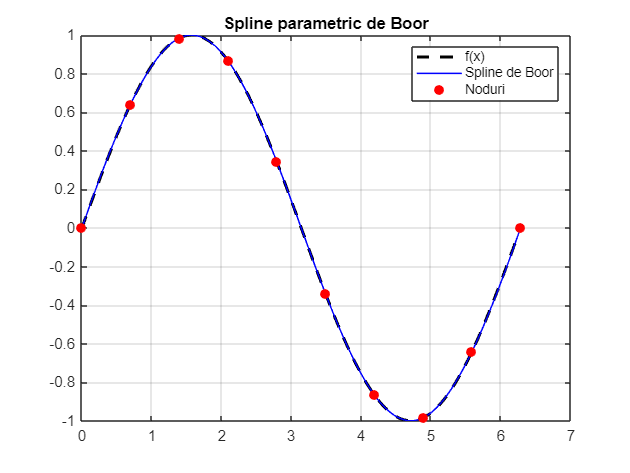

f = @(x) sin(x);           % functie de interpolat
a = 0; b = 2*pi;           % domeniu
n_noduri = 10;
n_eval = 400;

[xx, yy, pp_x, pp_y, eroare] = aplicaSplineBoor(f, a, b, n_noduri, n_eval);

% Grafic
figure;
plot(xx, f(xx), 'k--', 'LineWidth', 2); hold on;
plot(xx, yy, 'b-', 'LineWidth', 1);
plot(linspace(a, b, n_noduri), f(linspace(a, b, n_noduri)), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline de Boor', 'Noduri');
title('Spline parametric de Boor');
grid on;


fprintf('Eroare maxima spline de Boor: %.2e\n', eroare);

Eroare maxima spline de Boor: 4.41e-03
